# tall Arrays for Big Data in MATLAB

Copyright 2016 The MathWorks, Inc.    

## Example: Predict Cab Fare in New York City

- Analyze data based on time of day 

- Visualize and learn about neat time-of-day-based statistics

The goal is to get a simple yet meaningful understanding of the New York City Yellow Cab data from 2015 (there's more data going back several years.) The total size of the .csv files from 2015 is 21.3 GB. 

The data set is freely available from the [NYC Taxi & Limousine Commission](http://www.nyc.gov/html/tlc/html/about/trip_record_data.shtml). You only need one csv file to get things going.

## Define data access and processing parameters

Decide here whether or not you want to test the data on a smaller set of data, **and/or** whether or not you want to process your data on a Spark cluster.

useSparkCluster = 0; % 1 = true, 0 = false
useAllData = 0;

## Tell MATLAB where your .csv files are stored, as well as your Hadoop/Spark path

The following sub-script assumes that all the files you downloaded are stored in the same place. Please be sure to specify the correct paths.

allMyFilesAreStoredHere = 'path/to/your/data';

% You do not need to set these if you're just running on your local machine
hadoop_path = 'path/to/your/Hadoop';
spark_path = 'path/to/your/Spark';

addpath(allMyFilesAreStoredHere)


## Let's get it started!

if useSparkCluster
    numWorkers = 16; 
    setenv('HADOOP_HOME', hadoop_path);
    setenv('SPARK_HOME', spark_path);
    cluster = parallel.cluster.Hadoop;
    cluster.SparkProperties('spark.executor.instances') = num2str(numWorkers);
    mr = mapreducer(cluster);
end

% use all csv files found in the file
filePath = [allMyFilesAreStoredHere '*.csv'];
filePath = [allMyFilesAreStoredHere 'yellow_tripdata_2015-01.csv'];

% You don't have to specify data formats for the datastore, but it does helps MATLAB.
ds = datastore(filePath,...
        'TextscanFormats', ...
            {'%C', '%{yyyy-MM-dd HH:mm:ss}D', '%{yyyy-MM-dd HH:mm:ss}D', '%u8', '%f', ...
            '%f', '%f', '%C', '%C', '%f', '%f', '%C', '%f', '%f', '%f', '%f', '%f', '%f', '%f'});


## Examine column variables

Use this code to quickly reference the column names of your data

% for i = 1:size(ds.VariableNames,2)
%     disp([i,ds.VariableNames(1,i)])
% end

## **Select variables of interest (for your tall array) and give them more intuitive labels**

vars = [2:3,5,12:13,16,19];

Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.


ds.VariableNames(vars) = {'Pickup','Dropoff','TripDistance','PaymentType','Fare','Tip','Total'};

ds.SelectedVariableNames = ds.VariableNames(vars);

% If you decide not to specify data formats upfront when creating your datastore object, here's how to do it.
% Here's the time format for Pickup and Dropoff in the .csv's, which happen to be the first two selected variables.

% ds.SelectedFormats(1:2) = {'%{yyyy-MM-dd HH:mm:ss}D'}; 

## "Bring into" tall array

Read the datastore into a tall table. tt = tall(ds). Yep. That's it.

% Create tall array from datastore.
tt = tall(ds);

## Perform calculations/Derive values

For this exercise, let's calculate the following averages based on the hour of day:

1) trip duration (min) (**derived** value)

2) trip distance (mi) (**given** value)

3) cost per minute of trip ($/min) (based on "pre-tip amount" = fare + tolls = total - tip) (**derived** value)

4) tip percentage (%) (**derived** value)

5) average vehicle speed (mph) (**derived** value)

% These data columns don't exist before the line of code that references them.

% Derive new values intuitively with simple syntax. 
tt.HourOfDay = hour(tt.Pickup);
tt.TripDurationMinutes = minutes(tt.Dropoff - tt.Pickup);
tt.CostPerMinute = (tt.Total - tt.Tip)./tt.TripDurationMinutes;
tt.TipPercentage = tt.Tip./tt.Fare;
tt.AverageVehicleSpeed = tt.TripDistance./tt.TripDurationMinutes * 60;

## Remove outliers

% (Warning: takes a while.) Uncomment old_size and new_size code to see # entries removed.
% old_size = gather(size(tt,1));

idx = tt.TripDurationMinutes <= .5 | ...    % really short
    tt.TripDurationMinutes >=  60 * 4 | ... % unfeasibly long
    tt.TripDistance <= .25 | ...            % really short
    tt.TripDistance >= 1000 | ...           % unfeasibly far
    tt.Fare <= 0 | ...                      % negative fares
    tt.Fare > 1000 | ...                    % unfeasibly large fare 
    any(ismissing(tt),2);                   % missing data

% Use the following code to look at small criteria-defined subsets of your data
% idx = tt.Fare > 200 % just how many fares *were* exorbitantly large?
% subset = gather(tt(idx, :));

tt2 = tt(~idx, :);                           % create an array without these entries

% (Warning: takes a while.) Uncomment old_size and new_size code to see # entries removed.
% new_size = gather(size(tt,1));
% fprintf('%d entries removed.');

## Explore the data

Work with a subset of the data and determine grouped statistics by hour of day. 

% For prototyping, you can use a subset of your data
ttSubarray = tt2;
if ~useAllData
    ttSubarray = head(tt,20000);
end

vars = {'TripDistance','Fare','TripDurationMinutes','HourOfDay','CostPerMinute','Total','Tip','TipPercentage','AverageVehicleSpeed'};


## Gather results to workspace

Execute commands and gather results into the workspace.

% semicolon left off by default so you can see final results.
statsByHr = gather(grpstats(ttSubarray(:,vars),'HourOfDay')) %;

Evaluating tall expression using the Parallel Pool 'local':
�
- Pass 1 of 1: 0% complete
Evaluation 0% complete
���������������������������������������������������
- Pass 1 of 1: 17% complete
Evaluation 14% complete
�����������������������������������������������������
- Pass 1 of 1: 33% complete
Evaluation 28% complete
�����������������������������������������������������
- Pass 1 of 1: 50% complete
Evaluation 42% complete
�����������������������������������������������������
- Pass 1 of 1: 67% complete
Evaluation 56% complete
�����������������������������������������������������
- Pass 1 of 1: 83% complete
Evaluation 69% complete
�����������������������������������������������������
- Pass 1 of 1: 100% complete
Evaluation 83% complete
������������������������������������������������������
- Pass 1 of 1: Completed in 1.7833 min
�
Evaluation 83% complete
�������������������������
Evaluation 92% complete
�������������������������
Evaluation 92% complete
�������������������������
Evaluat

statsByHr =     GroupLabel    HourOfDay    GroupCount    mean_TripDistance    mean_Fare    mean_TripDurationMinutes    mean_CostPerMinute    mean_Total    mean_Tip    mean_TipPercentage    mean_AverageVehicleSpeed
    __________    _________    __________    _________________    _________    ________________________    __________________    __________    ________    __________________    ________________________

    '0'            0            886          3.4407               13.159       12.445                      1.2851                16.374        1.7666       0.1365               15.398                  
    '1'

## Explore model variables

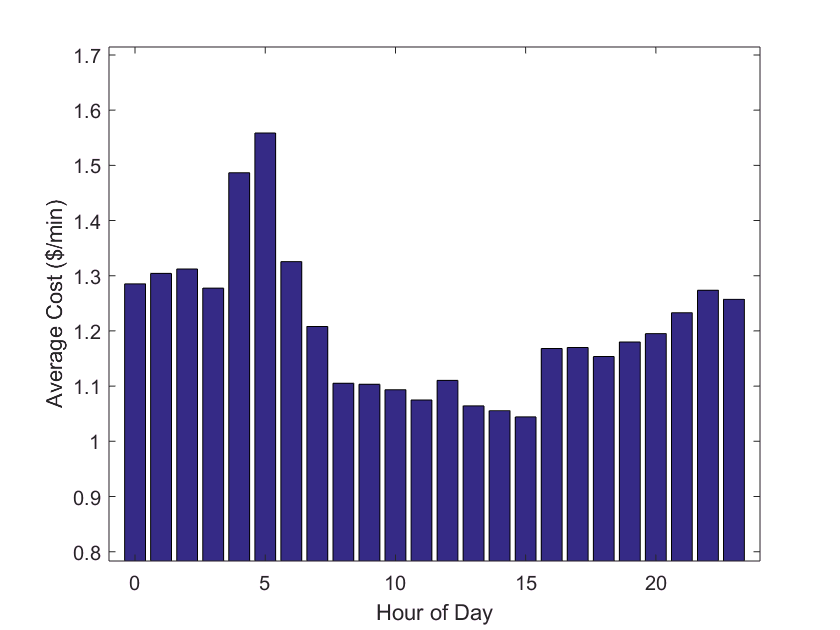

figure 

xaxis = statsByHr.HourOfDay;
yaxis = statsByHr.mean_CostPerMinute;
bar(xaxis, yaxis)
xlim([-1 24])
ylim([min(yaxis)*.75 max(yaxis)*1.1])

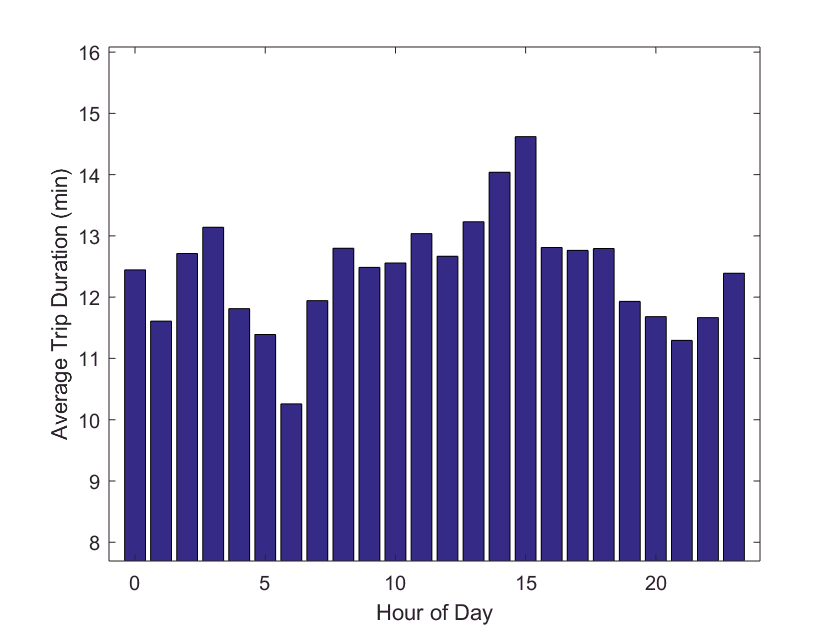

xlabel('Hour of Day')
ylabel('Average Cost ($/min)')

xaxis = statsByHr.HourOfDay;
yaxis = statsByHr.mean_TripDurationMinutes;
bar(xaxis, yaxis)
xlim([-1 24])
ylim([min(yaxis)*.75 max(yaxis)*1.1])

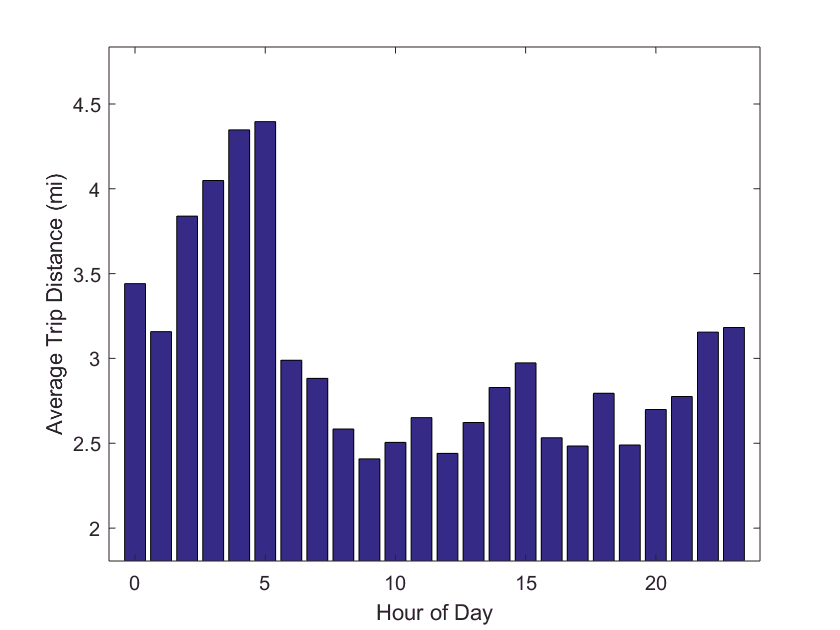

xlabel('Hour of Day')
ylabel('Average Trip Duration (min)')

xaxis = statsByHr.HourOfDay;
yaxis = statsByHr.mean_TripDistance;
bar(xaxis, yaxis)
xlim([-1 24])
ylim([min(yaxis)*.75 max(yaxis)*1.1])

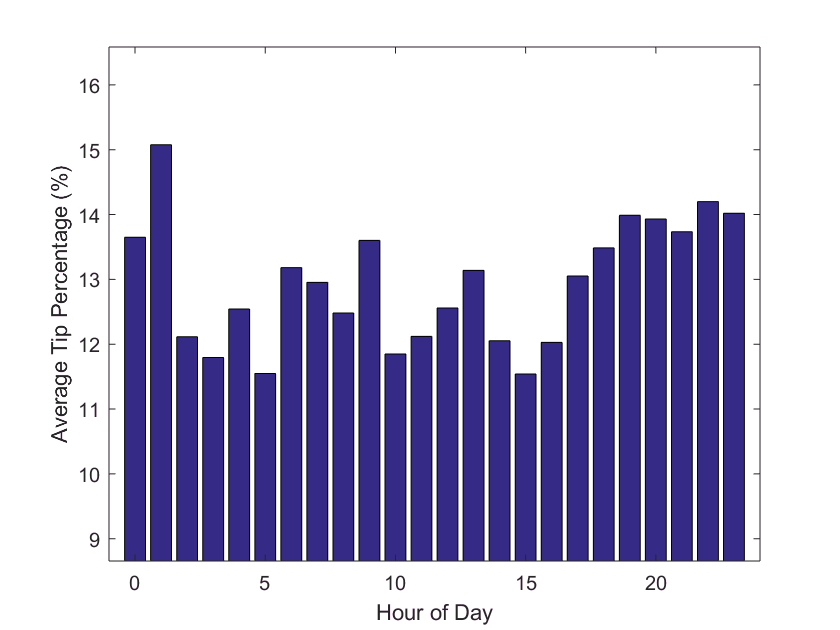

xlabel('Hour of Day')
ylabel('Average Trip Distance (mi)')

xaxis = statsByHr.HourOfDay;
yaxis = statsByHr.mean_TipPercentage*100;
bar(xaxis, yaxis)
xlim([-1 24])
ylim([min(yaxis)*.75 max(yaxis)*1.1])

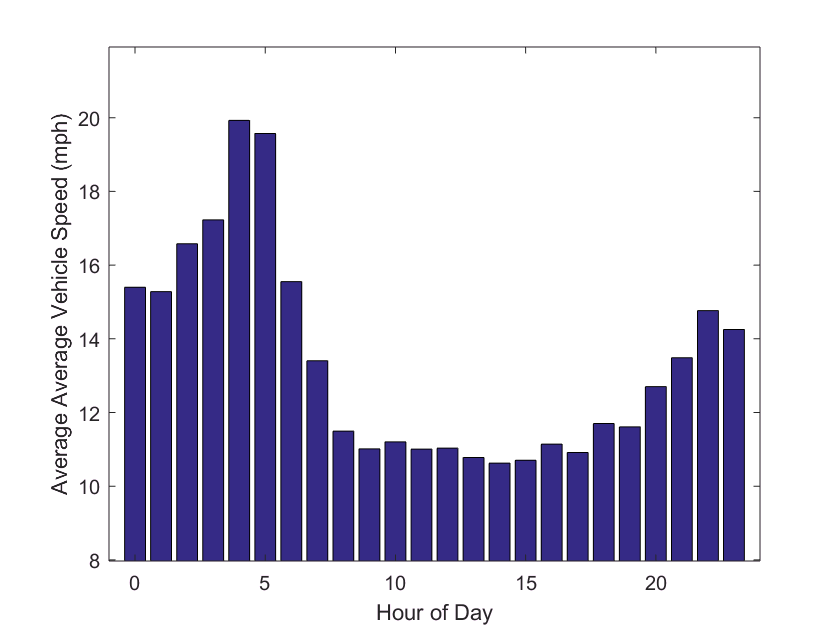

xlabel('Hour of Day')
ylabel('Average Tip Percentage (%)')

xaxis = statsByHr.HourOfDay;
yaxis = statsByHr.mean_AverageVehicleSpeed;
bar(xaxis, yaxis)
xlim([-1 24])
ylim([min(yaxis)*.75 max(yaxis)*1.1])

xlabel('Hour of Day')
ylabel('Mean Average Vehicle Speed (mph)') % this is a "double average"